## 数据导入-湖南省

filename = 'D:\Drivers\CarbonEmissiondata\Hunan_data.xlsx'; 
dataTable = readtable(filename);
%years = data.Year;  

% 对二氧化碳排放量进行插值CarbonEmissions_mt 缺少2019年的碳排放，使用三次样条计算后得到331.31
%carbonEmissionsIndex = ~ismissing(data.CarbonEmissions_mt); 
%data.CarbonEmissions_mt(carbonEmissionsIndex == 0) = interp1(years(carbonEmissionsIndex), data.CarbonEmissions_mt(carbonEmissionsIndex), years(carbonEmissionsIndex == 0), 'spline');

dataGDP_ren = dataTable.Per_capita_GDP_yuan(1:25);
dataGDP = dataGDP_ren.';

dataPopulation_wan = dataTable.Population_wan(1:25);
dataPopulation = dataPopulation_wan.';
disp(dataPopulation)

        6464        6497        6530        6563        6596        6629        6663        6698        6326        6342        6355        6380        6406        6570        6581        6590        6600        6611        6615        6625        6633        6635        6640        6645        6622



dataSecond_billion = dataTable.Value_added_of_the_secondary_industry_billion(1:25);
dataSecond = dataSecond_billion.';

dataCE_mt = dataTable.CarbonEmissions_mt(1:25);
%dataCE = dataCE_mt.';

dataCoal_tons = dataTable.Coal_consumption_10000_tons(1:25);
dataCoke_tons = dataTable.Coke_consumption_10000_tons(1:25);
dataFuel_tons = dataTable.Fuel_oil_consumption_10000_tons(1:25);
energyconsumption= (dataCoal_tons+dataCoke_tons+dataFuel_tons);
dataEnergy = energyconsumption.';
disp(dataEnergy)

   1.0e+04 *

    0.5374    0.5463    0.4414    0.4176    0.4861    0.5109    0.5888    0.7209    1.0157    1.0836    1.1865    1.1782    1.2329    1.3000    1.4624    1.4082    1.3246    1.2741    1.3166    1.3246    1.4122    1.2843    1.2582    1.1642    1.0871




dataNatural_meters = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25);
dataNaturalgas = dataNatural_meters.';

dataTechnology_million = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25);
dataTechnology = dataTechnology_million.';

%dataFirepower_kilowatt= dataTable.Thermal_power_generation_100_million_kilowatt_hours(1:26);
%dataFire = dataFirepower_kilowatt.';

dataWaterpower_kilowatt= dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25);
%dataWater = dataWaterpower_kilowatt.';

dataTotalpower_kilowatt= dataTable.Total_power_generation_100_million_kilowatt_hours(1:25);
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_2=(dataWaterpower_kilowatt/dataTotalpower_kilowatt);
%dataWaterpercent=dataWaterpercent_2.';


## 人均GDP的LSTM模型

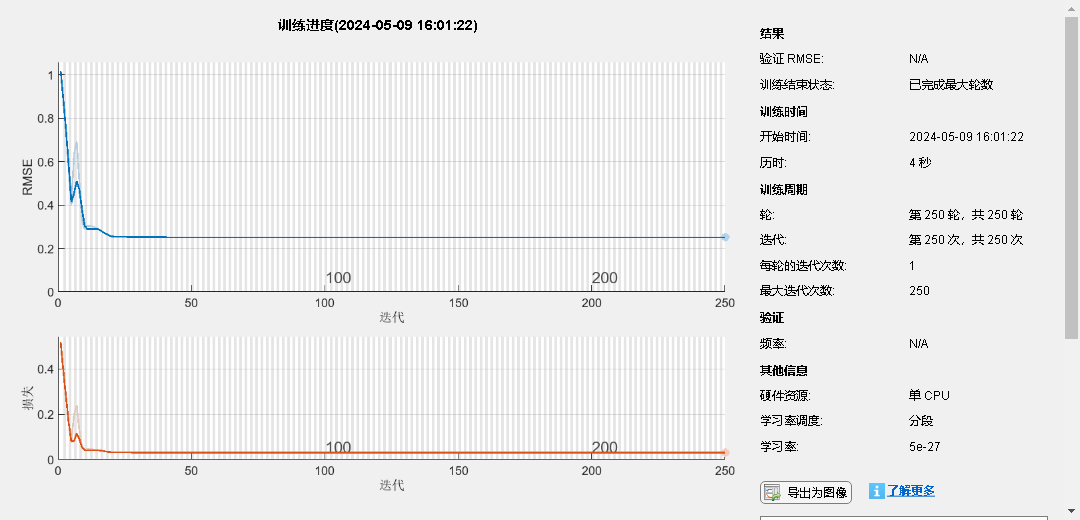

numTimeStepsTrain = numel(dataGDP); 
dataTrainGDP = dataGDP(1 : numTimeStepsTrain);
% 数据标准化，零均值和单位方差
muGDP = mean(dataTrainGDP);
sigGDP = std(dataTrainGDP);
dataTrainStandardizedGDP = (dataTrainGDP - muGDP) / sigGDP;
% 训练数据
XTrainGDP = dataTrainStandardizedGDP(1:end-1);
YTrainGDP = dataTrainStandardizedGDP(2:end);
% 创建 LSTM 网络
numFeaturesGDP = 1;
numResponsesGDP = 1;
numHiddenUnitsGDP = 100;

layersGDP = [sequenceInputLayer(numFeaturesGDP)
          lstmLayer(numHiddenUnitsGDP)
          fullyConnectedLayer(numResponsesGDP)
          regressionLayer];

% 设置网络参数
optionsGDP = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netGDP = trainNetwork(XTrainGDP, YTrainGDP, layersGDP, optionsGDP);

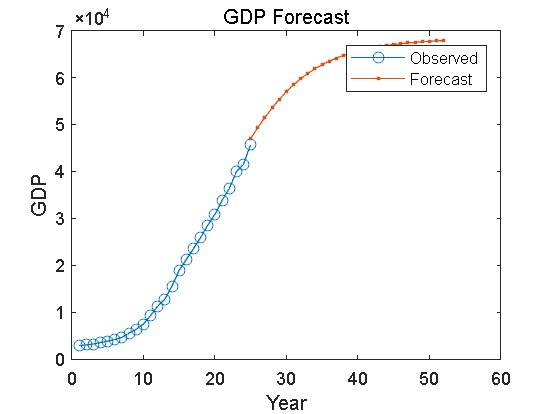

% 预测
netGDP = predictAndUpdateState(netGDP, XTrainGDP);
% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netGDP, YPredGDP] = predictAndUpdateState(netGDP, YTrainGDP(end));

% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictGDP = 28;
YPredGDP = [YPredGDP zeros(1, numYearsToPredictGDP - 1)]; % 预分配预测数组
for i = 2:numYearsToPredictGDP
    [netGDP, YPredGDP(:, i)] = predictAndUpdateState(netGDP, YPredGDP(:, i-1), 'ExecutionEnvironment', 'cpu');
end
% 去标准化
YPredGDP = sigGDP * YPredGDP + muGDP;
% 画图
figure;
plot(1:numel(dataGDP), dataGDP, '-o')
hold on
idx = numel(dataGDP) : (numel(dataGDP) + numYearsToPredictGDP - 1);
plot(idx, YPredGDP, '.-')
hold off 
xlabel("Year");
ylabel("GDP");
title("GDP Forecast");
legend("Observed", "Forecast");

%writematrix(YPred, 'D:\Drivers\LSTM_liaoningCEdata.xlsx'); % 修改为实际文件路径
disp(YPredGDP)

   1.0e+04 *

    4.6990    4.9346    5.1519    5.3513    5.5328    5.6964    5.8427    5.9725    6.0868    6.1870    6.2743    6.3502    6.4160    6.4729    6.5220    6.5645    6.6011    6.6327    6.6600    6.6835    6.7039    6.7215    6.7368    6.7500    6.7615    6.7715    6.7801    6.7877



## 人口的LSTM模型

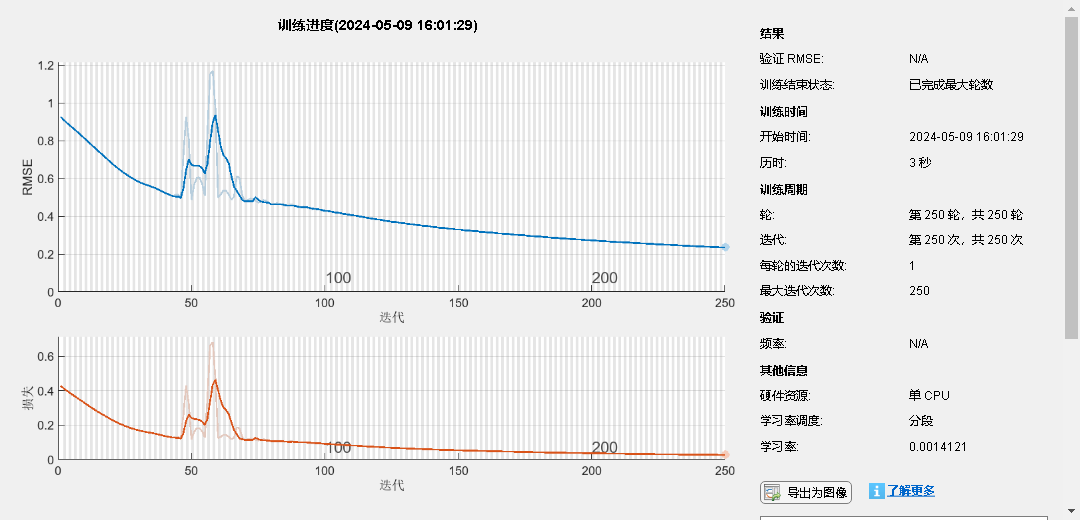

numTimeStepsTrainPopulation = numel(dataPopulation); % 使用所有的数据来训练
dataTrainPopulation = dataPopulation(1 : numTimeStepsTrainPopulation);

% 数据标准化，零均值和单位方差
muPopulation = mean(dataTrainPopulation);
sigPopulation = std(dataTrainPopulation);
dataTrainStandardizedPopulation = (dataTrainPopulation - muPopulation) / sigPopulation;

% 训练数据
XTrainPopulation = dataTrainStandardizedPopulation(1:end-1);
YTrainPopulation = dataTrainStandardizedPopulation(2:end);

% 创建 LSTM 网络
numFeaturesPopulation = 1;
numResponsesPopulation = 1;
numHiddenUnitsPopulation = 20;

layersPopulation = [sequenceInputLayer(numFeaturesPopulation)
          lstmLayer(numHiddenUnitsPopulation)
          fullyConnectedLayer(numResponsesPopulation)
          regressionLayer];

% 设置网络参数
optionsPopulation = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netPopulation = trainNetwork(XTrainPopulation, YTrainPopulation, layersPopulation, optionsPopulation);

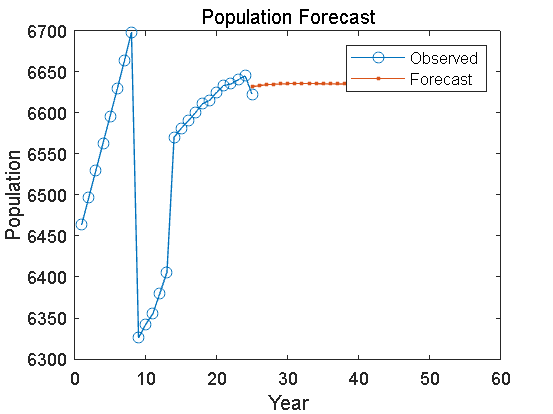


% 预测
netPopulation = predictAndUpdateState(netPopulation, XTrainPopulation);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netPopulation, YPredPopulation] = predictAndUpdateState(netPopulation, YTrainPopulation(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictPopulation = 28;
YPredPopulation = [YPredPopulation zeros(1, numYearsToPredictPopulation - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictPopulation
    [netPopulation, YPredPopulation(:, i)] = predictAndUpdateState(netPopulation, YPredPopulation(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredPopulation = sigPopulation * YPredPopulation + muPopulation;
% 画图
figure;
plot(1:numel(dataPopulation), dataPopulation, '-o')
hold on
idx = numel(dataPopulation) : (numel(dataPopulation) + numYearsToPredictPopulation - 1);
plot(idx, YPredPopulation, '.-')
hold off 
xlabel("Year");
ylabel("Population");
title("Population Forecast");
legend("Observed", "Forecast");

disp(YPredPopulation)

   1.0e+03 *

    6.6318    6.6330    6.6341    6.6347    6.6350    6.6352    6.6353    6.6353    6.6353    6.6353    6.6352    6.6351    6.6351    6.6350    6.6349    6.6349    6.6348    6.6348    6.6347    6.6347    6.6346    6.6346    6.6346    6.6346    6.6345    6.6345    6.6345    6.6345



## 第二产业的LSTM模型

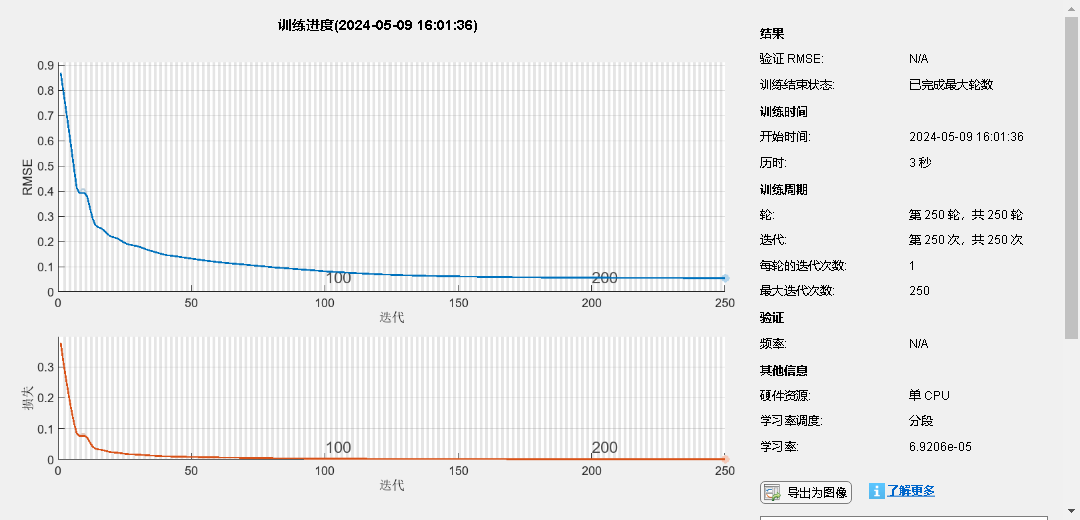

numTimeStepsTrainSecond = numel(dataSecond); 
dataTrainSecond = dataSecond(1 : numTimeStepsTrainSecond);

% 数据标准化，零均值和单位方差
musecond = mean(dataTrainSecond);
sigsecond = std(dataTrainSecond);
dataTrainStandardizedSecond = (dataTrainSecond - musecond) / sigsecond;

% 训练数据
XTrainSecond = dataTrainStandardizedSecond(1:end-1);
YTrainSecond = dataTrainStandardizedSecond(2:end);

% 创建 LSTM 网络
numFeaturesSecond= 1;
numResponsesSecond = 1;
numHiddenUnitsSecond = 40;

layersSecond = [sequenceInputLayer(numFeaturesSecond)
          lstmLayer(numHiddenUnitsSecond)
          fullyConnectedLayer(numResponsesSecond)
          regressionLayer];

% 设置网络参数
optionsSecond = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.7, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netSecond = trainNetwork(XTrainSecond, YTrainSecond, layersSecond, optionsSecond);

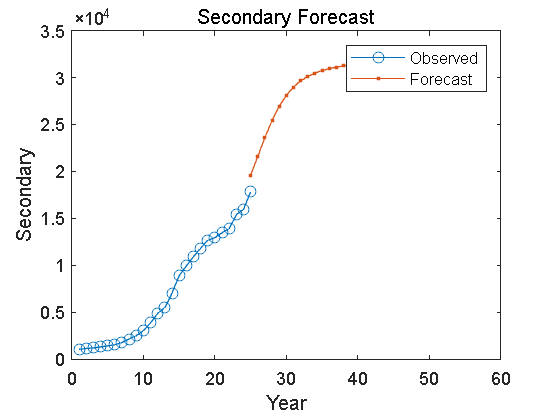


% 预测
netSecond = predictAndUpdateState(netSecond, XTrainSecond);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netSecond, YPredSecond] = predictAndUpdateState(netSecond, YTrainSecond(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictSecond = 28;
YPredSecond = [YPredSecond zeros(1, numYearsToPredictSecond - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictSecond
    [netSecond, YPredSecond(:, i)] = predictAndUpdateState(netSecond, YPredSecond(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredSecond = sigsecond * YPredSecond + musecond;
% 画图
figure;
plot(1:numel(dataSecond), dataSecond, '-o')
hold on
idx = numel(dataSecond) : (numel(dataSecond) + numYearsToPredictSecond - 1);
plot(idx, YPredSecond, '.-')
hold off 
xlabel("Year");
ylabel("Secondary");
title("Secondary Forecast");
legend("Observed", "Forecast");

disp(YPredSecond)

   1.0e+04 *

    1.9593    2.1605    2.3612    2.5430    2.6938    2.8111    2.8990    2.9639    3.0120    3.0478    3.0747    3.0953    3.1111    3.1235    3.1332    3.1410    3.1472    3.1523    3.1564    3.1598    3.1627    3.1650    3.1670    3.1687    3.1701    3.1713    3.1723    3.1732



## 煤炭等化石能源消耗量的LSTM模型

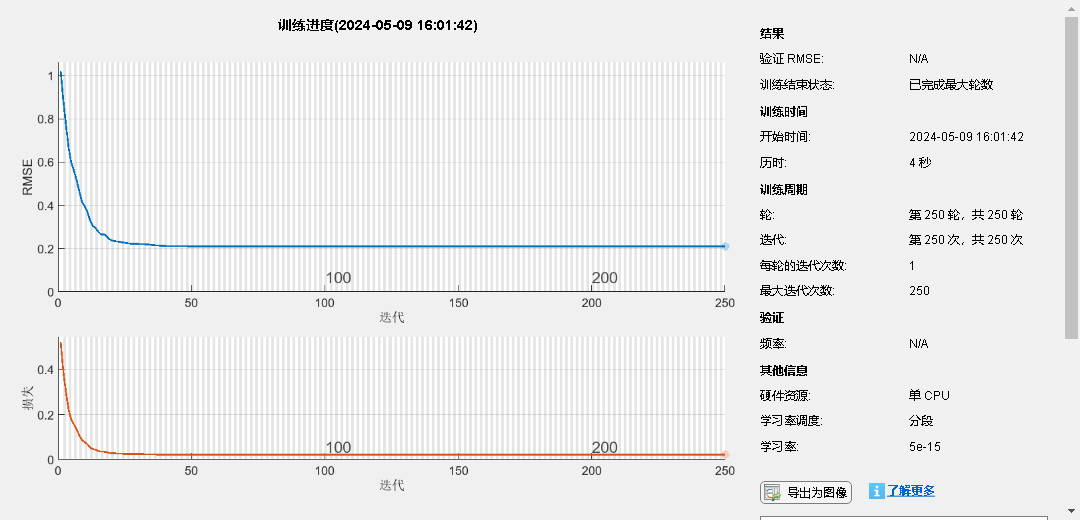

numTimeStepsTrainEnergy = numel(dataEnergy); 
dataTrainEnergy = dataEnergy(1 : numTimeStepsTrainEnergy);

% 数据标准化，零均值和单位方差
muEnergy = mean(dataTrainEnergy);
sigEnergy = std(dataTrainEnergy);
dataTrainStandardizedEnergy = (dataTrainEnergy - muEnergy) / sigEnergy;

% 训练数据
XTrainEnergy = dataTrainStandardizedEnergy(1:end-1);
YTrainEnergy = dataTrainStandardizedEnergy(2:end);

% 创建 LSTM 网络
numFeaturesEnergy= 1;
numResponsesEnergy = 1;
numHiddenUnitsEnergy = 100;

layersEnergy = [sequenceInputLayer(numFeaturesEnergy)
          lstmLayer(numHiddenUnitsEnergy)
          fullyConnectedLayer(numResponsesEnergy)
          regressionLayer];

% 设置网络参数
optionsEnergy = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同化石能源消耗背景下，改这个就行LearnRateDropFactor'
% 训练
netEnergy = trainNetwork(XTrainEnergy, YTrainEnergy, layersEnergy, optionsEnergy);

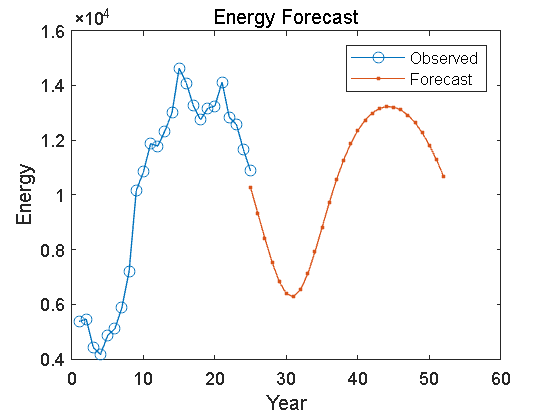


% 预测
netEnergy = predictAndUpdateState(netEnergy, XTrainEnergy);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netEnergy, YPredEnergy] = predictAndUpdateState(netEnergy, YTrainEnergy(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictEnergy = 28;
YPredEnergy = [YPredEnergy zeros(1, numYearsToPredictEnergy - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictEnergy
    [netEnergy, YPredEnergy(:, i)] = predictAndUpdateState(netEnergy, YPredEnergy(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredEnergy = sigEnergy * YPredEnergy + muEnergy;
% 画图
figure;
plot(1:numel(dataEnergy), dataEnergy, '-o')
hold on
idx = numel(dataEnergy) : (numel(dataEnergy) + numYearsToPredictEnergy - 1);
plot(idx, YPredEnergy, '.-')
hold off 
xlabel("Year");
ylabel("Energy");
title("Energy Forecast");
legend("Observed", "Forecast");

disp(YPredEnergy)

   1.0e+04 *

    1.0259    0.9329    0.8405    0.7541    0.6833    0.6386    0.6281    0.6541    0.7119    0.7917    0.8818    0.9718    1.0547    1.1270    1.1872    1.2355    1.2724    1.2987    1.3152    1.3225    1.3208    1.3104    1.2913    1.2635    1.2270    1.1818    1.1281    1.0669



## 天然气的LSTM模型

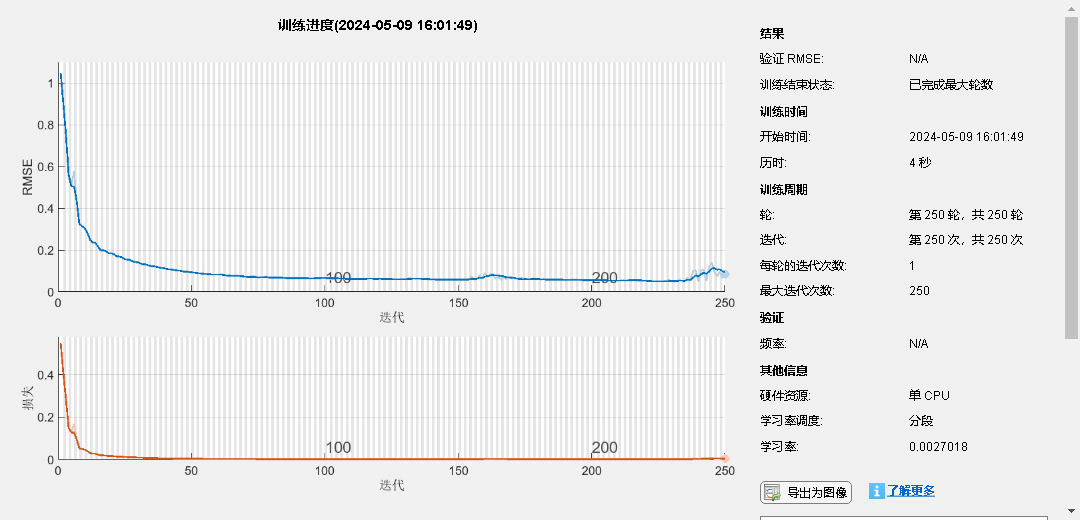

numTimeStepsTrainNaturalgas = numel(dataNaturalgas);
dataTrainNaturalgas = dataNaturalgas(1 : numTimeStepsTrainNaturalgas);

% 数据标准化，零均值和单位方差
muNaturalgas = mean(dataTrainNaturalgas);
sigNaturalgas = std(dataTrainNaturalgas);
dataTrainStandardizedNaturalgas = (dataTrainNaturalgas - muNaturalgas) / sigNaturalgas;

% 训练数据
XTrainNaturalgas = dataTrainStandardizedNaturalgas(1:end-1);
YTrainNaturalgas = dataTrainStandardizedNaturalgas(2:end);

% 创建 LSTM 网络
numFeaturesNaturalgas= 1;
numResponsesNaturalgas = 1;
numHiddenUnitsNaturalgas = 100;

layersNaturalgas = [sequenceInputLayer(numFeaturesNaturalgas)
          lstmLayer(numHiddenUnitsNaturalgas)
          fullyConnectedLayer(numResponsesNaturalgas)
          regressionLayer];

% 设置网络参数
optionsNaturalgas = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.95, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Naturalgas背景下，改这个就行LearnRateDropFactor'
% 训练
netNaturalgas = trainNetwork(XTrainNaturalgas, YTrainNaturalgas, layersNaturalgas, optionsNaturalgas);

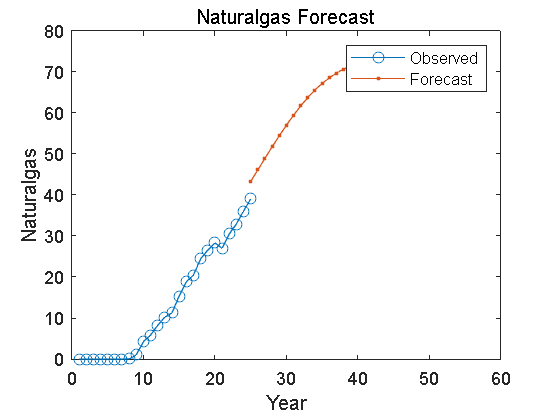


% 预测
netNaturalgas = predictAndUpdateState(netNaturalgas, XTrainNaturalgas);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netNaturalgas, YPredNaturalgas] = predictAndUpdateState(netNaturalgas, YTrainNaturalgas(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictNaturalgas = 28;
YPredNaturalgas = [YPredNaturalgas zeros(1, numYearsToPredictNaturalgas - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictNaturalgas
    [netNaturalgas, YPredNaturalgas(:, i)] = predictAndUpdateState(netNaturalgas, YPredNaturalgas(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredNaturalgas = sigNaturalgas * YPredNaturalgas + muNaturalgas;
% 画图
figure;
plot(1:numel(dataNaturalgas), dataNaturalgas, '-o')
hold on
idx = numel(dataNaturalgas) : (numel(dataNaturalgas) + numYearsToPredictNaturalgas - 1);
plot(idx, YPredNaturalgas, '.-')
hold off 
xlabel("Year");
ylabel("Naturalgas");
title("Naturalgas Forecast");
legend("Observed", "Forecast");

disp(YPredNaturalgas)

   43.2636   46.0578   48.8952   51.6739   54.3729   56.9550   59.3868   61.6397   63.6903   65.5209   67.1220   68.4937   69.6460   70.5971   71.3703   71.9911   72.4847   72.8741   73.1795   73.4179   73.6031   73.7465   73.8568   73.9412   74.0052   74.0531   74.0884   74.1137



## 科技发展LSTM模型

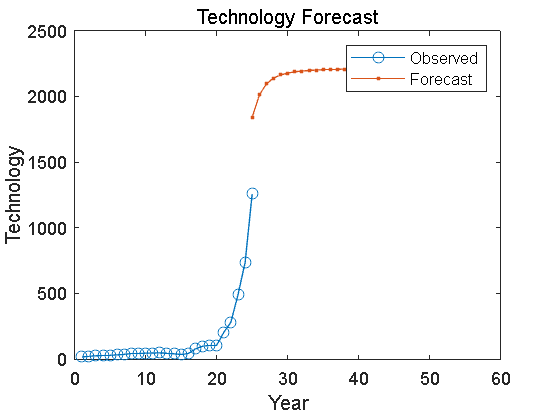

numTimeStepsTrainTechnology = numel(dataTechnology); 
dataTrainTechnology = dataTechnology(1 : numTimeStepsTrainTechnology);

% 数据标准化，零均值和单位方差
muTechnology = mean(dataTrainTechnology);
sigTechnology = std(dataTrainTechnology);
dataTrainStandardizedTechnology = (dataTrainTechnology - muTechnology) / sigTechnology;

% 训练数据
XTrainTechnology = dataTrainStandardizedTechnology(1:end-1);
YTrainTechnology = dataTrainStandardizedTechnology(2:end);

% 创建 LSTM 网络
numFeaturesTechnology= 1;
numResponsesTechnology = 1;
numHiddenUnitsTechnology = 100;

layersTechnology = [sequenceInputLayer(numFeaturesTechnology)
          lstmLayer(numHiddenUnitsTechnology)
          fullyConnectedLayer(numResponsesTechnology)
          regressionLayer];

% 设置网络参数
optionsTechnology = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.01, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，改这个就'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netTechnology = trainNetwork(XTrainTechnology, YTrainTechnology, layersTechnology, optionsTechnology);

% 预测
netTechnology = predictAndUpdateState(netTechnology, XTrainTechnology);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netTechnology, YPredTechnology] = predictAndUpdateState(netTechnology, YTrainTechnology(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictTechnology = 28;
YPredTechnology = [YPredTechnology zeros(1, numYearsToPredictTechnology - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictTechnology
    [netTechnology, YPredTechnology(:, i)] = predictAndUpdateState(netTechnology, YPredTechnology(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredTechnology = sigTechnology * YPredTechnology + muTechnology;
% 画图
figure;
plot(1:numel(dataTechnology), dataTechnology, '-o')
hold on
idx = numel(dataTechnology) : (numel(dataTechnology) + numYearsToPredictTechnology - 1);
plot(idx, YPredTechnology, '.-')
hold off 
xlabel("Year");
ylabel("Technology");
title("Technology Forecast");
legend("Observed", "Forecast");

disp(YPredTechnology)

   1.0e+03 *

    1.8406    2.0101    2.0947    2.1383    2.1624    2.1769    2.1861    2.1923    2.1967    2.1999    2.2023    2.2042    2.2058    2.2070    2.2080    2.2088    2.2095    2.2101    2.2106    2.2111    2.2114    2.2118    2.2121    2.2123    2.2125    2.2127    2.2129    2.2131



## 水力发电的百分占比LSTM模型

dataWaterpercent_2= dataTable.WaterPercent(1:25);
dataWaterpercent_1=dataWaterpercent_2*100;
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_1=(dataWaterpower_kilowatt / dataTotalpower_kilowatt)*100;
dataWaterpercent=dataWaterpercent_1.';
disp(dataWaterpercent);

   1.0e+04 *

    1.9299    1.9369    1.6538    1.9115    2.1201    2.2793    2.4297    2.8093    2.4128    2.9069    3.1256    4.0700    4.0943    5.0253    4.5903    5.0175    5.0714    5.3587    5.7252    6.2151    5.9737    5.3723    5.4397    5.7366    5.8805



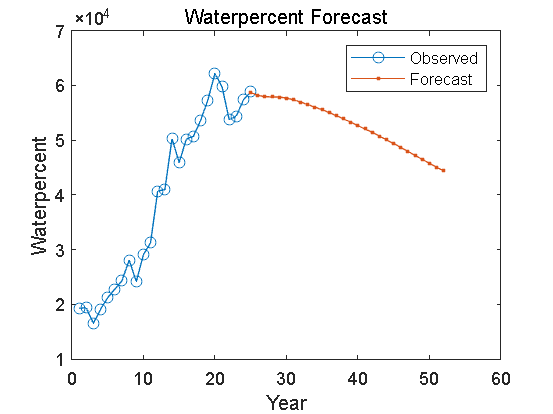


numTimeStepsTrainWaterpercent = numel(dataWaterpercent); % 使用所有的数据来训练
dataTrainWaterpercent = dataWaterpercent(1 : numTimeStepsTrainWaterpercent);

% 数据标准化，零均值和单位方差
muWaterpercent = mean(dataTrainWaterpercent);
sigWaterpercent = std(dataTrainWaterpercent);
dataTrainStandardizedWaterpercent = (dataTrainWaterpercent - muWaterpercent) / sigWaterpercent;

% 训练数据
XTrainWaterpercent = dataTrainStandardizedWaterpercent(1:end-1);
YTrainWaterpercent = dataTrainStandardizedWaterpercent(2:end);

% 创建 LSTM 网络
numFeaturesWaterpercent= 1;
numResponsesWaterpercent = 1;
numHiddenUnitsWaterpercent = 130;

layersWaterpercent = [sequenceInputLayer(numFeaturesWaterpercent)
          lstmLayer(numHiddenUnitsWaterpercent)
          fullyConnectedLayer(numResponsesWaterpercent)
          regressionLayer];

% 设置网络参数
optionsWaterpercent = trainingOptions('adam', ...
    'MaxEpochs', 550, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

netWaterpercent = trainNetwork(XTrainWaterpercent, YTrainWaterpercent, layersWaterpercent, optionsWaterpercent);

% 预测
netWaterpercent = predictAndUpdateState(netWaterpercent, XTrainWaterpercent);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netWaterpercent, YPredWaterpercent] = predictAndUpdateState(netWaterpercent, YTrainWaterpercent(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictWaterpercent = 28;
YPredWaterpercent = [YPredWaterpercent zeros(1, numYearsToPredictWaterpercent - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictWaterpercent
    [netWaterpercent, YPredWaterpercent(:, i)] = predictAndUpdateState(netWaterpercent, YPredWaterpercent(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredWaterpercent = sigWaterpercent * YPredWaterpercent + muWaterpercent;
% 画图
figure;
plot(1:numel(dataWaterpercent), dataWaterpercent, '-o')
hold on
idx = numel(dataWaterpercent) : (numel(dataWaterpercent) + numYearsToPredictWaterpercent - 1);
plot(idx, YPredWaterpercent, '.-')
hold off 
xlabel("Year");
ylabel("Waterpercent");
title("Waterpercent Forecast");
legend("Observed", "Forecast");

disp(YPredWaterpercent)

   1.0e+04 *

    5.8686    5.8182    5.7924    5.7895    5.7864    5.7685    5.7355    5.6936    5.6485    5.6020    5.5533    5.5012    5.4456    5.3872    5.3270    5.2657    5.2031    5.1391    5.0734    5.0059    4.9369    4.8663    4.7945    4.7217    4.6485    4.5759    4.5054    4.4390



## 原始STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Hunan_data.xlsx'; 
dataTable = readtable(filename);

dataPopulation = dataTable.Population_wan(1:25) * 1e4; % 人口
dataGDP = dataTable.Per_capita_GDP_yuan(1:25); % 人均GDP
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25); % 技术市场交易量
dataEmission = dataTable.CarbonEmissions_mt(1:25); % 碳排放量

% 创建数据矩阵
dataMatrix = [dataPopulation, dataGDP, dataTechnology, dataEmission];

% 对数转换
dataLog = log(dataMatrix + 1); % 加1是为了避免对0取对数

% 将对数转换后的数据转换为dataTable
dataTableLog = array2table(dataLog, 'VariableNames', {'LogPopulation', 'LogGDP', 'LogTechnology', 'LogEmission'});

% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 变量名
variableNames = {'Population', 'GDP', 'Technology', 'Emission'};

% 相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                  Population      GDP      Technology    Emission
                  __________    _______    __________    ________

    Population            1     0.35203     0.40308      0.076021
    GDP             0.35203           1     0.83106       0.90932
    Technology      0.40308     0.83106           1       0.58237
    Emission       0.076021     0.90932     0.58237             1




% 绘制热力图
%figure;
%h = heatmap(variableNames, variableNames, correlationMatrix);
%h.Title = 'Pearson Correlation Matrix Heatmap';
%h.Colormap = bone; % 颜色映射选择
%h.ColorScaling = 'scaledcolumns'; % 颜色标准化

% 拟合模型
lm_formula = 'LogEmission ~ LogPopulation + LogGDP + LogTechnology';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogEmission ~ 1 + LogPopulation + LogGDP + LogTechnology

估计系数:
                     Estimate       SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept)        109.33      22.885     4.7775    0.00010153
    LogPopulation     -6.0968      1.2737    -4.7865     9.937e-05
    LogGDP            0.68352    0.036887      18.53    1.7161e-14
    LogTechnology    -0.20451    0.032446    -6.3032    2.9914e-06


观测值数目: 25，误差自由度: 21
均方根误差: 0.0965
R 方: 0.964，调整 R 方 0.958
F 统计量(常量模型): 186，p 值 = 2.86e-15


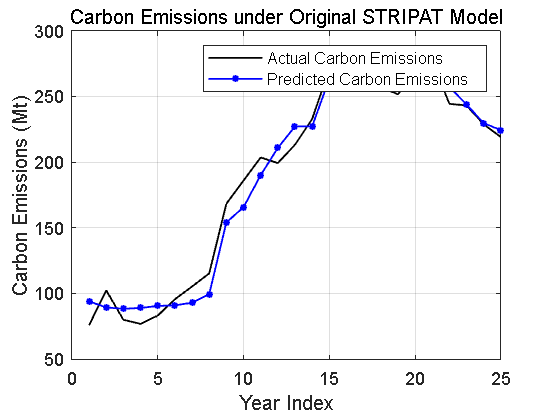


% 原始结果曲线图
figure;
plot(exp(dataTableLog.LogEmission), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Original STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 改良STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Hunan_data.xlsx'; 
dataTable = readtable(filename);

% 数据提取与转换 重新提取一下 变原单位
dataGDP = dataTable.Per_capita_GDP_yuan(1:25);
dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataSecond = dataTable.Value_added_of_the_secondary_industry_billion(1:25) * 1e9;
dataCE = dataTable.CarbonEmissions_mt(1:25);
energyconsumption = (dataTable.Coal_consumption_10000_tons(1:25) + dataTable.Coke_consumption_10000_tons(1:25) + dataTable.Fuel_oil_consumption_10000_tons(1:25)) * 1e4;
dataNaturalgas = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25) * 1e9;
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25) * 1e8;
hydroPower = dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
totalPower = dataTable.Total_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
dataWaterPercent = (hydroPower ./ totalPower) * 100;

% 数据标准化处理
dataMatrix = [dataCE, dataGDP, dataPopulation, dataSecond, energyconsumption, dataNaturalgas, dataTechnology, dataWaterPercent];

dataLog = log(dataMatrix+1);
% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 定义变量名称
variableNames = {'CarbonEmissions', 'GDP', 'Population', 'SecondaryIndustry', 'EnergyConsumption', 'NaturalGas', 'TechnologyTransactions', 'HydroPowerPercentage'};

% 输出相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                              CarbonEmissions      GDP       Population    SecondaryIndustry    EnergyConsumption    NaturalGas    TechnologyTransactions    HydroPowerPercentage
                              _______________    ________    __________    _________________    _________________    __________    ______________________    ____________________

    CarbonEmissions                     1         0.90932     0.076021           0.9307               0.98613          0.94674             0.58597                 -0.80857      
    GDP                           0.90932               1      0.35203          0.99737               0.86362          0.85738             0.83331                 -0.76241      
    Population                   0.076021         0.35203            1          0.32996             -0.021109        -0.032349             0.40303                 0.011656      
    SecondaryIndustry              0.9307         0.99737      0.32996                1               0.88797

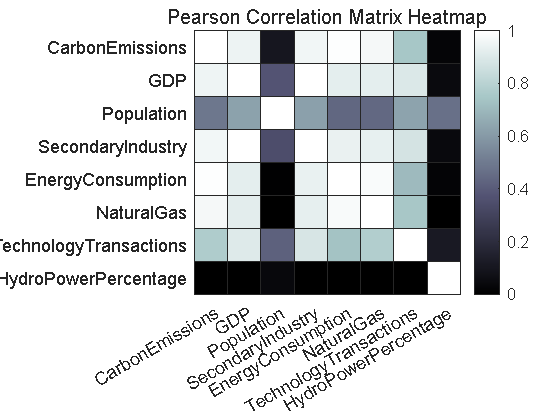


% 热力图
figure; % jet太难看了 换个颜色 winter也难看 pink不错 就bone了
%mycolor = [0.474509803921569,0.650980392156863,0.807843137254902;...
% 0.682352941176471,0.823529411764706,0.898039215686275;...
 %0.941176470588235,0.972549019607843,0.862745098039216;...
 %0.992156862745098,0.968627450980392,0.705882352941177;...
 %1,0.901960784313726,0.603921568627451];
h = heatmap(variableNames, variableNames, correlationMatrix);
h.Title = 'Pearson Correlation Matrix Heatmap';
h.Colormap = bone; 
h.ColorScaling = 'scaledcolumns'; 

%colormap(gca,mycolor);


% 创建数据表格
variableNames = {'LogCE','LogGDP', 'LogPopulation', 'LogSecond',  'LogEnergyConsumption', 'LogNaturalGas', 'LogTechnology', 'LogWaterPercent'};
dataTableLog = array2table(dataLog, 'VariableNames', variableNames);

% 拟合模型
lm_formula = 'LogCE ~ LogPopulation + LogGDP + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogCE ~ 1 + LogGDP + LogPopulation + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent

估计系数:
                             Estimate        SE         tStat        pValue  
                            __________    ________    _________    __________

    (Intercept)                -20.422      26.526      -0.7699       0.45193
    LogGDP                      -0.465      0.4629      -1.0045       0.32921
    LogPopulation             -0.18778      1.2369     -0.15182       0.88112
    LogSecond                   0.5837     0.39534       1.4765        0.1581
    LogEnergyConsumption       0.86964      0.1965       4.4256    0.00037029
    LogNaturalGas           -0.0054467     0.00509      -1.0701       0.29955
    LogTechnology             0.017782    0.059334       0.2997       0.76804
    LogWaterPercent         -0.0036788     0.17679    -0.020809       0.98364


观测值数目: 25，误差自由度: 17
均方根误差: 0.0582
R 方: 0.989，调整 R 方 0.985
F 统计量(常量模型): 225，p 值

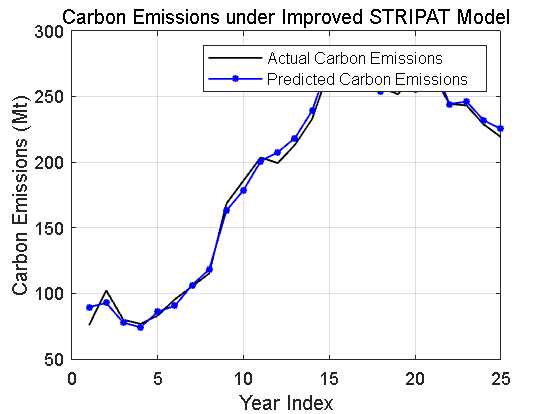


% 结果曲线图
figure;
plot(exp(dataTableLog.LogCE), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Improved STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 将预测得到的各个YPred的LSTM值带入到改良STRIPAT模型

YPredLogGDP = log(YPredGDP).';  % 取对数并转置
YPredLogPopulation = log(YPredPopulation).';
YPredLogSecond = log(YPredSecond).';
YPredLogEnergy = log(YPredEnergy).';
YPredLogNaturalGas = log(YPredNaturalgas).';
YPredLogTechnology = log(YPredTechnology).';
YPredLogWaterPercent = log(YPredWaterpercent).';
dataCE = dataTable.CarbonEmissions_mt(1:25); % 真实碳排放数据
Years = dataTable.Year(1:25); 

% 计算预测的碳排放
PredictedLogCE = -43.758 + (-0.50407 * YPredLogGDP) + (1.7038 * YPredLogPopulation) + (0.3175 * YPredLogSecond) + ...
                 (0.47877 * YPredLogEnergy) + (0.0045985 * YPredLogNaturalGas) + (0.27879 * YPredLogTechnology) + ...
                 (0.041688 * YPredLogWaterPercent);

% 将对数形式的预测碳排放转换回原始尺度
PredictedCE_1 = exp(PredictedLogCE);
PredictedCE = (PredictedCE_1)*1e13-130;
% 输出预测结果
disp('Predicted CarbonEmissions for future years:');

Predicted CarbonEmissions for future years:


disp(PredictedCE);

  226.5360
  221.4727
  210.5428
  196.7362
  183.1972
  173.4604
  170.5061
  175.3694
  186.7192
  201.8176
  217.9024
  233.0110
  246.1206
  256.9114
  265.4353
  271.9070
  276.5662
  279.6213
  281.2355
  281.5188
  280.5380
  278.3155
  274.8406
  270.0752
  263.9650
  256.4549
  247.5149
  237.1752



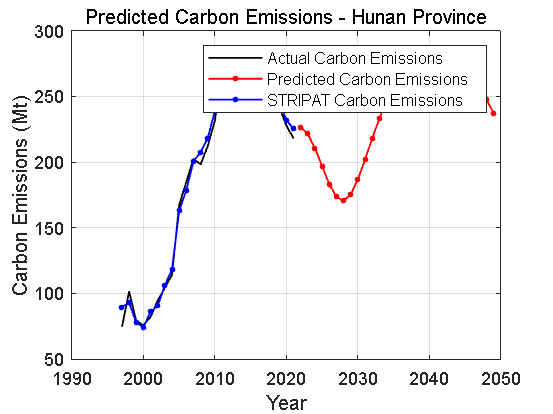

% 绘制实际与预测的碳排放量对比图
figure;
plot(Years, dataCE, 'k', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Actual Carbon Emissions');
hold on;
plot(Years(1) + (25:52), PredictedCE, 'r*-', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Predicted Carbon Emissions');
%STRIPATPred=exp(PredictedCE);
plot(Years(1)+ (0:24), exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'STRIPAT Carbon Emissions');
title('Predicted Carbon Emissions - Hunan Province');
xlabel('Year');
ylabel('Carbon Emissions (Mt)');
legend show;
grid on;
hold off;